DNN

% housekeeping 

% add folder with helper function tp to path
function_folder = fullfile(pwd, 'functions');
addpath(function_folder)

cfg = struct;
cfg.subNums = [102:108, 110:129];
%cfg.subNums = 4:37;
cfg.n = length(cfg.subNums);

cfg.categories = {'bathroom', 'kitchen'};
cfg.exp_num = 2;
cfg.colormaps = load('white_zero_colormap.mat');
d = struct;


% load images and get DNN representation
images = load_images(cfg);

Loaded image: 102_bath1_3D.png
Loaded image: 102_bath2_3D.png
Loaded image: 102_bath3_3D.png
Loaded image: 103_bath1_3D.png
Loaded image: 103_bath2_3D.png
Loaded image: 103_bath3_3D.png
Loaded image: 104_bath1_3D.png
Loaded image: 104_bath2_3D.png
Loaded image: 104_bath3_3D.png
Loaded image: 105_bath1_3D.png
Loaded image: 105_bath2_3D.png
Loaded image: 105_bath3_3D.png
Loaded image: 106_bath1_3D.png
Loaded image: 106_bath2_3D.png
Loaded image: 106_bath3_3D.png
Loaded image: 107_bath1_3D.png
Loaded image: 107_bath2_3D.png
Loaded image: 107_bath3_3D.png
Loaded image: 108_bath1_3D.png
Loaded image: 108_bath2_3D.png
Loaded image: 108_bath3_3D.png
Loaded image: 110_bath1_3D.png
Loaded image: 110_bath2_3D.png
Loaded image: 110_bath3_3D.png
Loaded image: 111_bath1_3D.png
Loaded image: 111_bath2_3D.png
Loaded image: 111_bath3_3D.png
Loaded image: 112_bath1_3D.png
Loaded image: 112_bath2_3D.png
Loaded image: 112_bath3_3D.png
Loaded image: 113_bath1_3D.png
Loaded image: 113_bath2_3D.png
Loaded i

analysis typical - layer #1 - category: bathroom
Length of labels do not match matrix dimensions


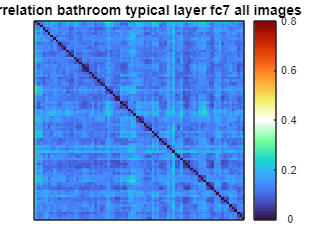

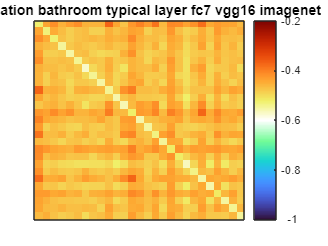

analysis typical - layer #1 - category: kitchen
Length of labels do not match matrix dimensions


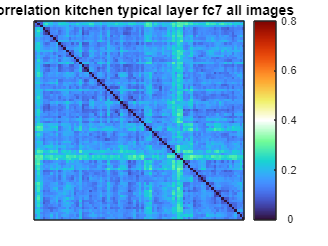

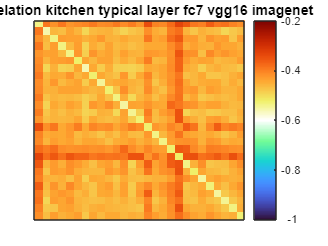


% typical images 
cfg.analysis_name = 'typical';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis control - layer #1 - category: bathroom
Length of labels do not match matrix dimensions


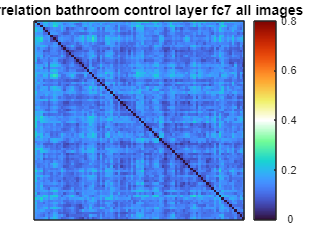

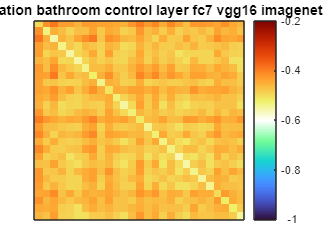

analysis control - layer #1 - category: kitchen
Length of labels do not match matrix dimensions


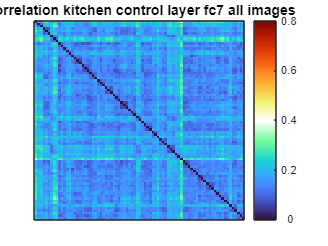

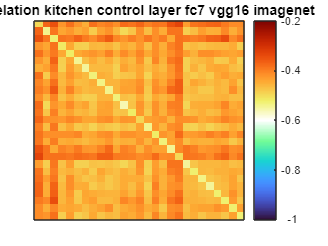


% control images 
cfg.analysis_name = 'control';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

Gaze

a_preprocessing(cfg)

Files for subject 102 already exist. Subject will be skipped
Files for subject 103 already exist. Subject will be skipped
Files for subject 104 already exist. Subject will be skipped
Files for subject 105 already exist. Subject will be skipped
Files for subject 106 already exist. Subject will be skipped
Files for subject 107 already exist. Subject will be skipped
Files for subject 108 already exist. Subject will be skipped
Files for subject 110 already exist. Subject will be skipped
Files for subject 111 already exist. Subject will be skipped
Files for subject 112 already exist. Subject will be skipped
Files for subject 113 already exist. Subject will be skipped
Files for subject 114 already exist. Subject will be skipped
Files for subject 115 already exist. Subject will be skipped
Files for subject 116 already exist. Subject will be skipped
Files for subject 117 already exist. Subject will be skipped
Files for subject 118 already exist. Subject will be skipped
Files for subject 119 al

b_detFix(cfg)

Files for subject 102 already exist. Subject will be skipped
Files for subject 103 already exist. Subject will be skipped
Files for subject 104 already exist. Subject will be skipped
Files for subject 105 already exist. Subject will be skipped
Files for subject 106 already exist. Subject will be skipped
Files for subject 107 already exist. Subject will be skipped
Files for subject 108 already exist. Subject will be skipped
Files for subject 110 already exist. Subject will be skipped
Files for subject 111 already exist. Subject will be skipped
Files for subject 112 already exist. Subject will be skipped
Files for subject 113 already exist. Subject will be skipped
Files for subject 114 already exist. Subject will be skipped
Files for subject 115 already exist. Subject will be skipped
Files for subject 116 already exist. Subject will be skipped
Files for subject 117 already exist. Subject will be skipped
Files for subject 118 already exist. Subject will be skipped
Files for subject 119 al

%c_showFix
d_AOIfix(cfg)

Loading AOIs...
Loading AOI masks for: sun_azxetkujrgobhzbi.jpg
Loading AOI masks for: sun_azwwluglgwfhhwee.jpg
Loading AOI masks for: sun_azqyogdvyhahyram.jpg
Loading AOI masks for: sun_azqlhsjgbwpcseew.jpg
Loading AOI masks for: sun_azkonpsbldzbkqim.jpg
Loading AOI masks for: sun_azgmgniivgpqrqvu.jpg
Loading AOI masks for: sun_azfvmsmpvphupjpu.jpg
Loading AOI masks for: sun_azdnupmzwdxwflvh.jpg
Loading AOI masks for: sun_azckywjqzicxsgez.jpg
Loading AOI masks for: sun_azbzyzntqpgdoyyu.jpg
Loading AOI masks for: sun_azbjiqtpgvxjjuzr.jpg
Loading AOI masks for: sun_aywpszwfywdmgrpv.jpg
Loading AOI masks for: sun_ayqukzphzqiguvnc.jpg
Loading AOI masks for: sun_aykqizkgpgmqzxbh.jpg
Loading AOI masks for: sun_ayhqvuklxnmflgid.jpg
Loading AOI masks for: sun_ayfwodsvoatztibh.jpg
Loading AOI masks for: sun_aydxycepjgosoubm.jpg
Loading AOI masks for: sun_aydtmlqdhvvmjvaq.jpg
Loading AOI masks for: sun_axvbhkthyolfaqez.jpg
Loading AOI masks for: sun_axuvsdqqnoevzlud.jpg
Loading AOI masks for: s


d = e_makeGDM(d, cfg);
d = e_makeGDM_firstFix(d, cfg);


Split half correlation

% split half correlation
cfg.conditions = {'fixCount',...
    'objectCate', 'objectCateFirstFix',...
    'singleObjects', 'singleObjectsFirstFix',...
    'ObjectCatePrio'};
cfg.correlation_type = 'pearson';
d = getSpliHalfReliability(d, cfg);

 
Fixation count
r: 0.57971, p = 6.7031e-33
10% of permutations of is done
20% of permutations of is done
30% of permutations of is done
40% of permutations of is done
50% of permutations of is done
60% of permutations of is done
70% of permutations of is done
80% of permutations of is done
90% of permutations of is done
100% of permutations of is done
 
Split-half reliablity for bathroom images
 
Single object dwell time
r: 0.70789, p = 1.2066e-54
10% of permutations of is done
20% of permutations of is done
30% of permutations of is done
40% of permutations of is done
50% of permutations of is done
60% of permutations of is done
70% of permutations of is done
80% of permutations of is done
90% of permutations of is done
100% of permutations of is done
 
Category dwell time
r: 0.22565, p = 1.9757e-05
10% of permutations of is done
20% of permutations of is done
30% of permutations of is done
40% of permutations of is done
50% of permutations of is done
60% of permutations of is done
7

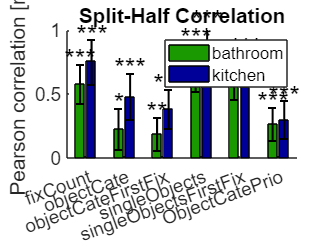

plotSpliHalfReliability(d, cfg);

Get inter-subject correlation

cfg.variables_of_interest = {};
cfg.variables_of_interest = {'ObjectFixCount',...
    'ObjectDwellsMulti', 'Objects_firstFix',...
    'ObjectDwellsMultiCate', 'ObjectsCate_firstFix',...
    'ObjectCatePrio'};
cfg.regressOutMean = true;
[d] = intersub_cor(d, cfg);

Plotting and saving inter-subject RDM for task:ObjectFixCount and bathroom
Plotting and saving inter-subject RDM for task:ObjectDwellsMulti and bathroom


Compare them

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of ObjectFixCount bathroom is done
20% of permutations of ObjectFixCount bathroom is done
30% of permutations of ObjectFixCount bathroom is done
40% of permutations of ObjectFixCount bathroom is done
50% of permutations of ObjectFixCount bathroom is done
60% of permutations of ObjectFixCount bathroom is done
70% of permutations of ObjectFixCount bathroom is done
80% of permutations of ObjectFixCount bathroom is done
90% of permutations of ObjectFixCount bathroom is done
100% of permutations of ObjectFixCount bathroom is done
Compare inter-subject RDM of ObjectFixCount with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of ObjectFixCount kitchen is done
20% of permutations of ObjectFixCount kitchen is done
30% of permutations of ObjectFixCount kitchen is done
40% of permutations of ObjectFixCount kitchen is done
50% of permutations

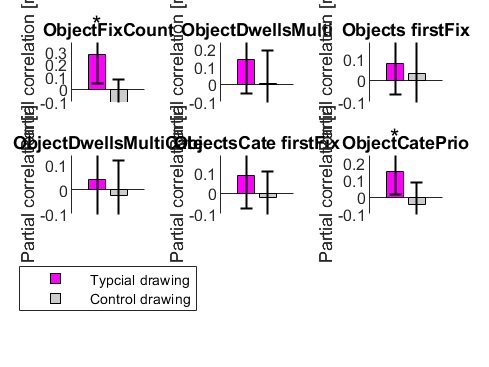

% preparation
cfg.partial_cor = true;
cfg.plot_rdm = false;
cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
cfg.predictor_RDMs = {'typical_late', 'control_late'};
cfg.tasks_of_interest = {'ObjectFixCount',...
    'ObjectDwellsMulti', 'Objects_firstFix',...
    'ObjectDwellsMultiCate', 'ObjectsCate_firstFix',...
    'ObjectCatePrio'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'bar';
cfg.show_single_cate = false;
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.permutation_type = 'row_col_shuffle_pred';

cfg.partial_correlation_type = 'pearson';

d = compare_task_RDMs_to_predictor_RDMs(d, cfg);